### P1 Ex Parcial 2Q 2023-24

#### Problema 1

Consider the bar shown in the top figure, with constant section $A = 1 \text{mm}^{2}$. It consists of two parts of equal length $h = 1 \text{m}$; the left side, with Young modulus $E = 0.10 \text{GPa}$and the right side, with Young modulus $E = 0.20 \text{GPa}$ ($1 \text{GPa} = 10^{9} \text{N/mm}^{2}$).

On the left, at a distance $d = 10 \text{cm}$ from the bar, there is a spring with constant $k_{\ell} = 2.00 \text{N/mm}$. On the right, at a distance $d = 10 \text{cm}$ from the bar, there is a spring with spring constant $k_{r} = 1.00 \text{N/mm}$.

The bar is stretched by the forces applied when we attach the springs to the endpoints of the bar until reaching an equilibrium (bottom figure). The bar is discretized using two linear 1D finite elements. The origin $x = 0$ is at the left endpoint.

**Recall: **when a spring is stretched or compressed, so that its lenght changes by an amount $x$ from its equilibrium length, then it exerts a force $F = -kx$ in a direction towards its equilibrium position.

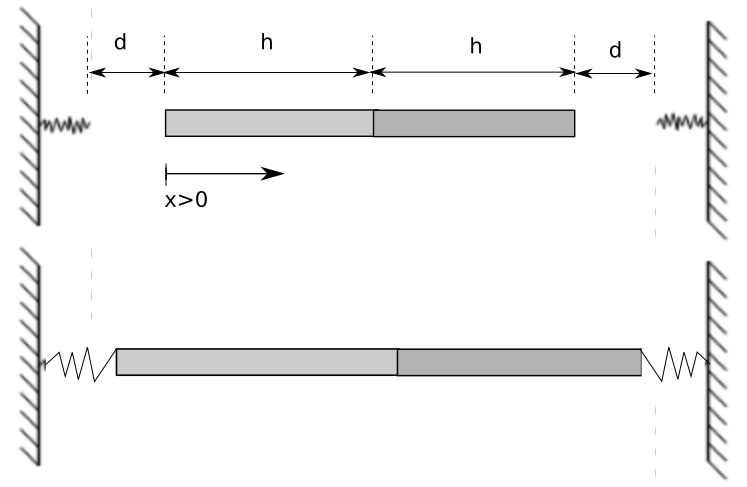

(a) (4 points) The displacement of the bar's midpoint is

clearvars
close all

A = 1.0;     %m^2
d = 1.0e2;   %mm
h = 1.0e3;   %mm
E1 = 1.0e2;  %N/mm^2 (left)
k1 = 2.00;   %N/mm   (left)
E2 = 2.0e2;  %N/mm^2 (right)
k2 = 1.00;   %N/mm   (right)

K1 = A*E1*[1,-1;-1,1]/h; K2 = A*E2*[1,-1;-1,1]/h

K2 =    2.0000e-01  -2.0000e-01
  -2.0000e-01   2.0000e-01



K = zeros(3);
Q = zeros(3,1);
u = zeros(3,1);

rows = [1; 2]; cols = rows;
K(rows,cols) = K(rows,cols) + K1

K =    1.0000e-01  -1.0000e-01            0
  -1.0000e-01   1.0000e-01            0
            0            0            0


rows = [2; 3]; cols = rows;
K(rows,cols) = K(rows,cols) + K2

K =    1.0000e-01  -1.0000e-01            0
  -1.0000e-01   3.0000e-01  -2.0000e-01
            0  -2.0000e-01   2.0000e-01


Km = K

Km =    1.0000e-01  -1.0000e-01            0
  -1.0000e-01   3.0000e-01  -2.0000e-01
            0  -2.0000e-01   2.0000e-01



Q(1) = -d*k1;
Q(3) = d*k2;
Km(1,1) = Km(1,1) + k1

Km =    2.1000e+00  -1.0000e-01            0
  -1.0000e-01   3.0000e-01  -2.0000e-01
            0  -2.0000e-01   2.0000e-01


Km(3,3) = Km(3,3) + k2

Km =    2.1000e+00  -1.0000e-01            0
  -1.0000e-01   3.0000e-01  -2.0000e-01
            0  -2.0000e-01   1.2000e+00


[Km, Q]

ans =    2.1000e+00  -1.0000e-01            0  -2.0000e+02
  -1.0000e-01   3.0000e-01  -2.0000e-01            0
            0  -2.0000e-01   1.2000e+00   1.0000e+02


u = Km\Q;
fprintf('Solution: u(h) = %9.4e mm (Hint. u(0) = %9.4e mm)\n', u(2), u(1))

Solution: u(h) = 2.7273e+01 mm (Hint. u(0) = -9.3939e+01 mm)


Solution. $u(2)\approx U_{2} = \text{2.7273e+01} \text{mm}$ (*Hint.* $u(0)\approx U_{1} = \text{-9.3939e+01} \text{mm}$)

(b) (3 points)  Find the displacement $u\left(\frac{4h}{3}\right)$:

Psi = @(x) [1-x/1000, x/1000; 2-x/1000, x/1000-1];
psi = Psi(h/3)

psi =    6.6667e-01   3.3333e-01
   1.6667e+00  -6.6667e-01


U1 = u(1)*psi(1,1) + u(2)*psi(1,2)

U1 =   -5.3535e+01


psi = Psi(4*h/3) 

psi =   -3.3333e-01   1.3333e+00
   6.6667e-01   3.3333e-01


U2 = u(2)*psi(2,1) + u(3)*psi(2,2)

U2 =    4.7475e+01


fprintf('Solution: U(4h/3) = %9.4e mm (Hint. U(h/3) = %9.4e mm)\n',U2,U1)

Solució: U(4h/3) = 4.7475e+01 mm (Hint. U(h/3) = -5.3535e+01 mm)


Solution. $u\left(\frac{4h}{3}\right) \approx \text{4.7475e+01mm}$ (*Hint. *$u\left(\frac{h}{3}\right)\approx \text{-5.3535e+01} \text{mm}$).

(d) (3 points) The secondary variable $Q_{n}$ at the right endpoint is:

%Post process
Q = K*u;
fprintf('Solution: Qn = %9.4e N\n',Q(3))

Solució Qn = 1.2121e+01 N


Solution. $q_{n} \approx Q_{3} = \text{1.2121e+01 \text{N}$.